# Superficies

#### Ejemplo 1

Gráfica de un paraboloide hiperbólico. 

La función **meshgrid** nos permite generar una retícula de puntos para distintos valores de "x" y "y". Dicha retícula se representa por dos matrices para los valores de "x" y "y". La unión de puntos contiguos de la retícula se le conoce como **malla** (mesh).

La función **surf** nos permite representar la superficie en el espacio 3D. La función **colorbar** nos permite mostrar el mapa de colores, con lo cual es posible codificar los colores del gráfico.

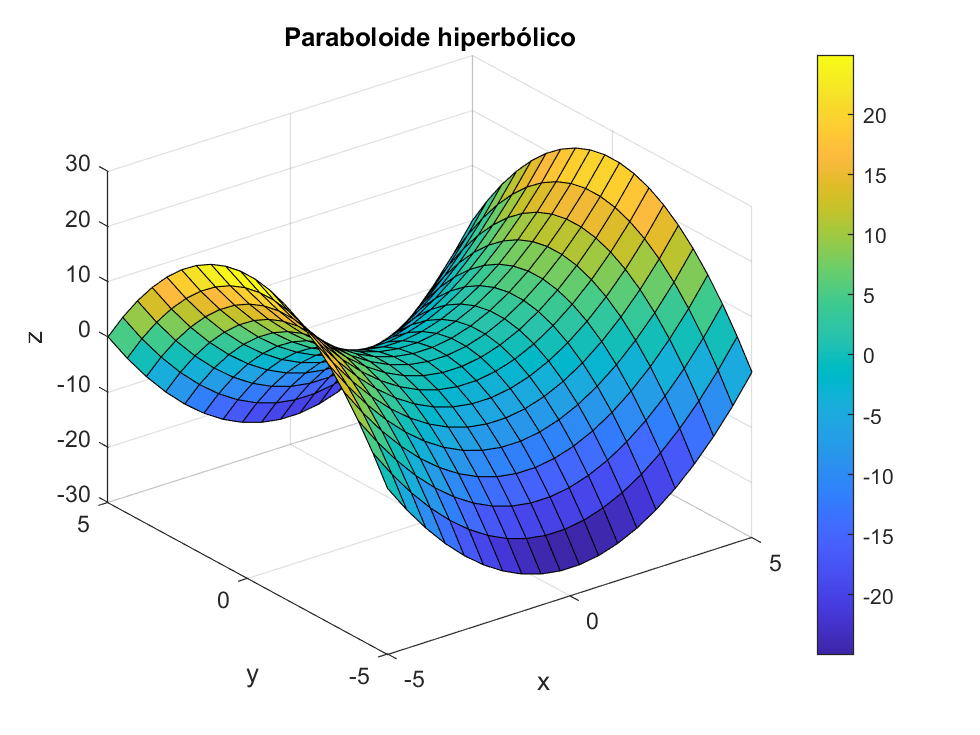

xl = linspace(-5,5,20); % Valores de x (entre -5 y 5)
yl = linspace(-5,5,20); % Valores de y (entre -5 y 5)

% Malla de valores x, y
[x, y] = meshgrid(xl, yl);

% Calcula los valores de z para los puntos de la malla
z = x.^2 - y.^2;

% Gráfica de la función con surf
surf(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide hiperbólico')
colorbar

La función **mesh** nos permite graficar las lineas que limitan la malla.

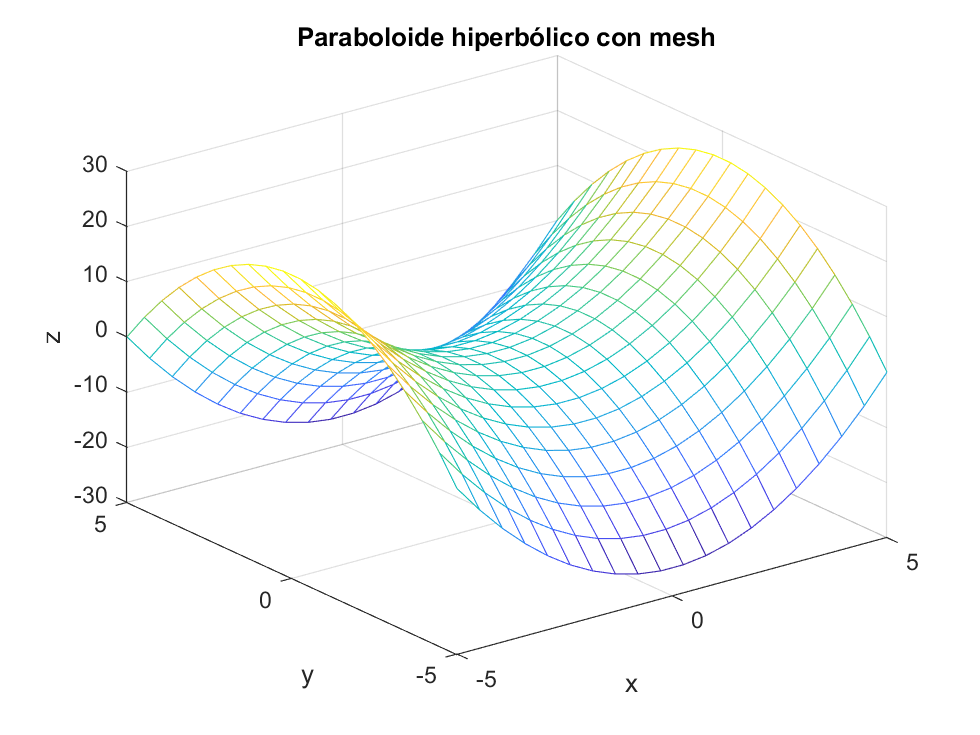

% Gráfica de la función con mesh
mesh(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide hiperbólico con mesh')

La función **countour** permite ver las curvas de nivel de la superficie.

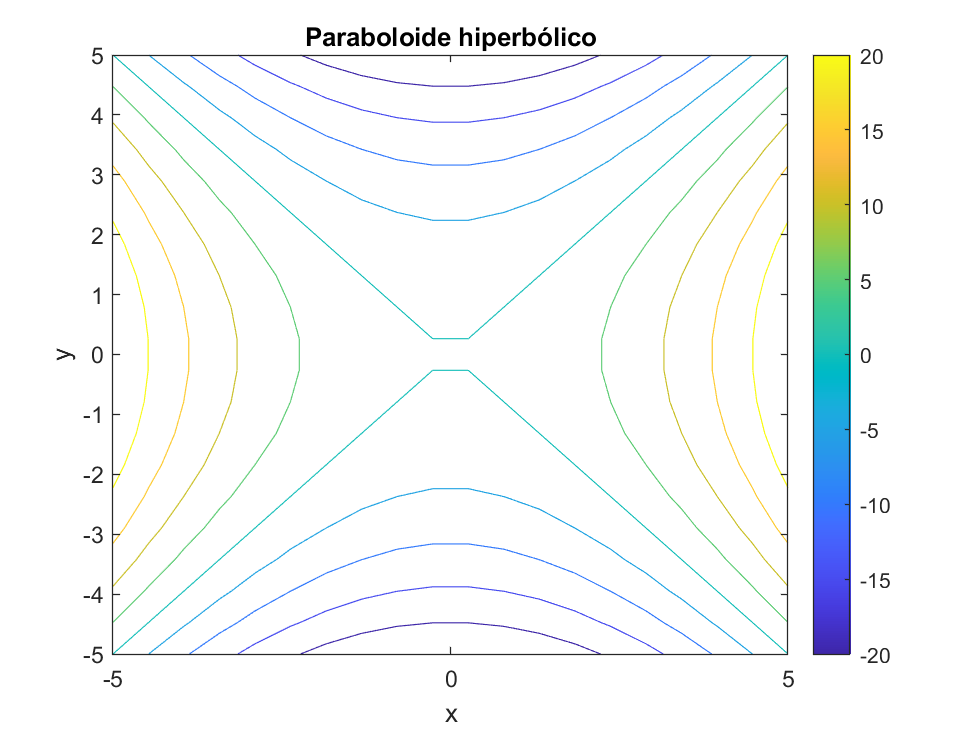

% Gráfica de las curvas de nivel de la función
contour(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide hiperbólico')
colorbar

La función **surfc** permite ver las curvas de nivel junto con la superficie 3D.

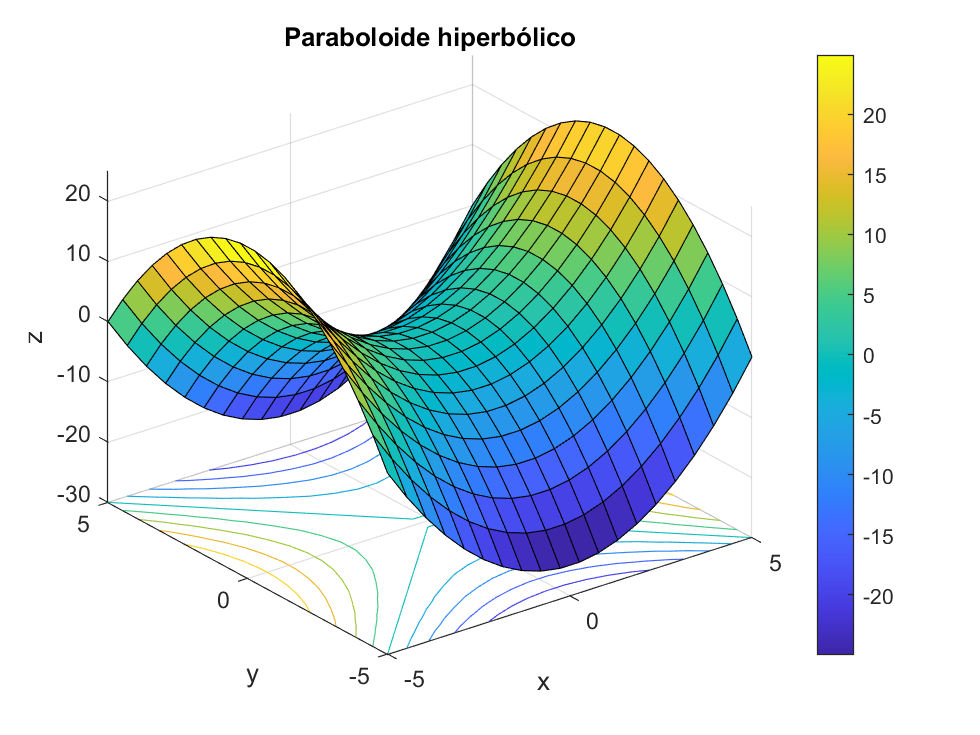

% Gráfica de la función con surfc
surfc(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide hiperbólico')
colorbar

Para cambiar los límites de un gráfico, se pueden utilizar las funciones **xlim**, **ylim**, **zlim** y **axes**.

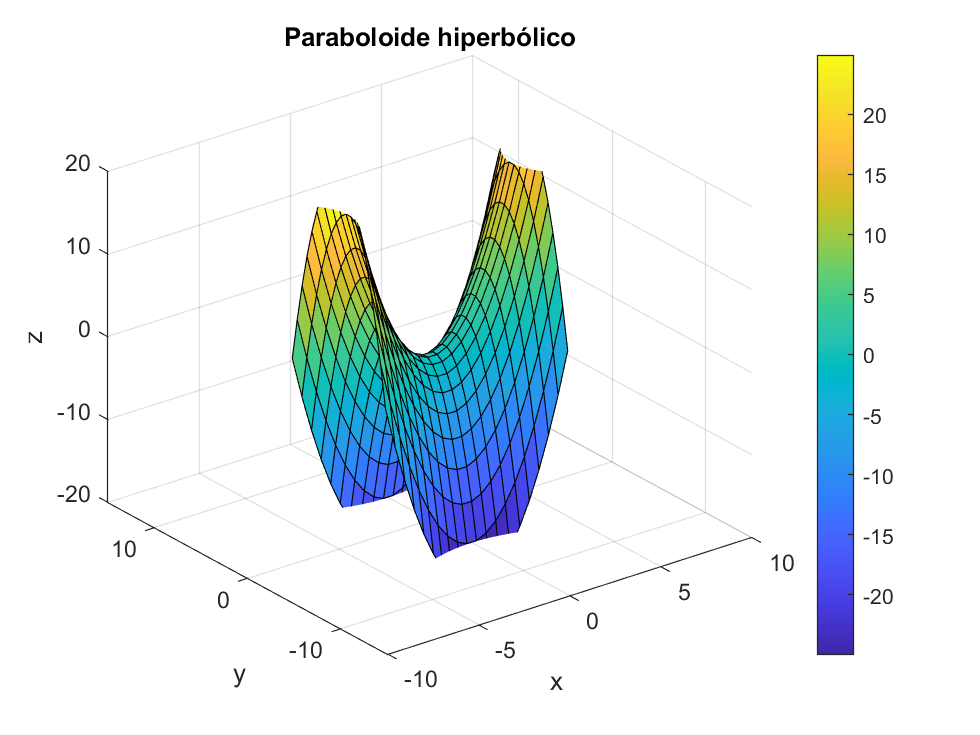

% Gráfica de la función con surfc
surfc(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide hiperbólico')
colorbar

% Lo siguiente es equivalente a axis([-10, 10, -15, 15, -20, 20])
xlim([-10,10])
ylim([-15,15])
zlim([-20,20])

#### Ejemplo 2

Gráfica de un plano.

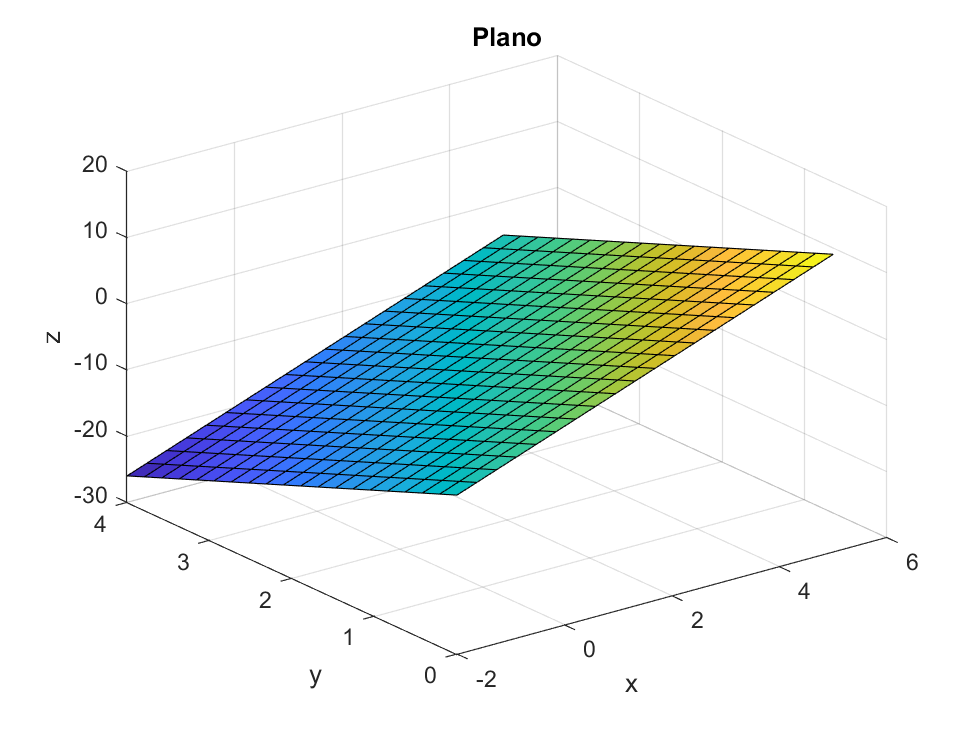

xl = linspace(-2,5,20); % Valores de x (entre -2 y 5)
yl = linspace(0,4,20);  % Valores de y (entre 0 y 4)

% Malla de valores x, y
[x, y] = meshgrid(xl, yl);

% Calcula los valores de z para los puntos de la malla
z = 3*x - 5*y;

% Gráfica de la función
surf(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Plano')

#### Ejemplo 3

Gráfica de un paraboloide elíptico.

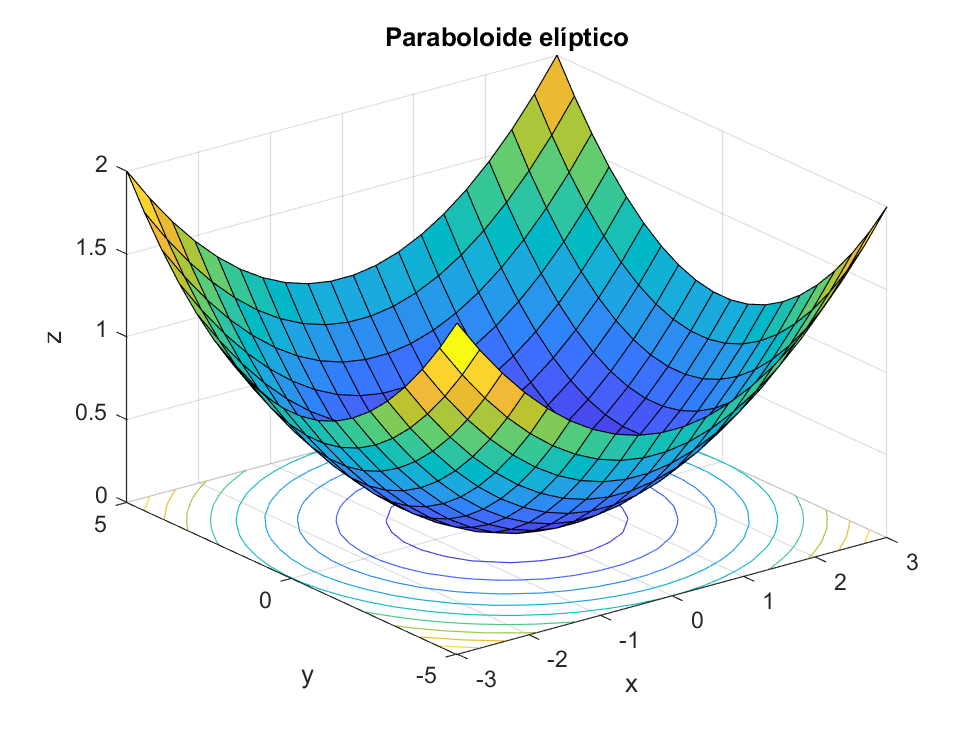

xl = linspace(-3,3,20);  % Valores de x (entre -3 y 3)
yl = linspace(-5,5,20);  % Valores de y (entre -5 y 5)

% Retícula de valores x, y
[x, y] = meshgrid(xl, yl);

% Calcula los valores de z para los puntos de la malla
z = (x/3).^2 + (y/5).^2;

% Gráfica de la función
surfc(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide elíptico')

#### Ejemplo 4

Gráfica de un paraboloide elíptico con ecuaciones paramétricas. 

La propiedad **FaceColor** permite cambiar el color de la superficie. La propieda **EdgeColor** permite cambiar el color de las líneas de la malla, y **FaceAlpha** permite controlar la transparencia. Un valor de **none** permite deshabilitar la propiedad que estén definiendo.

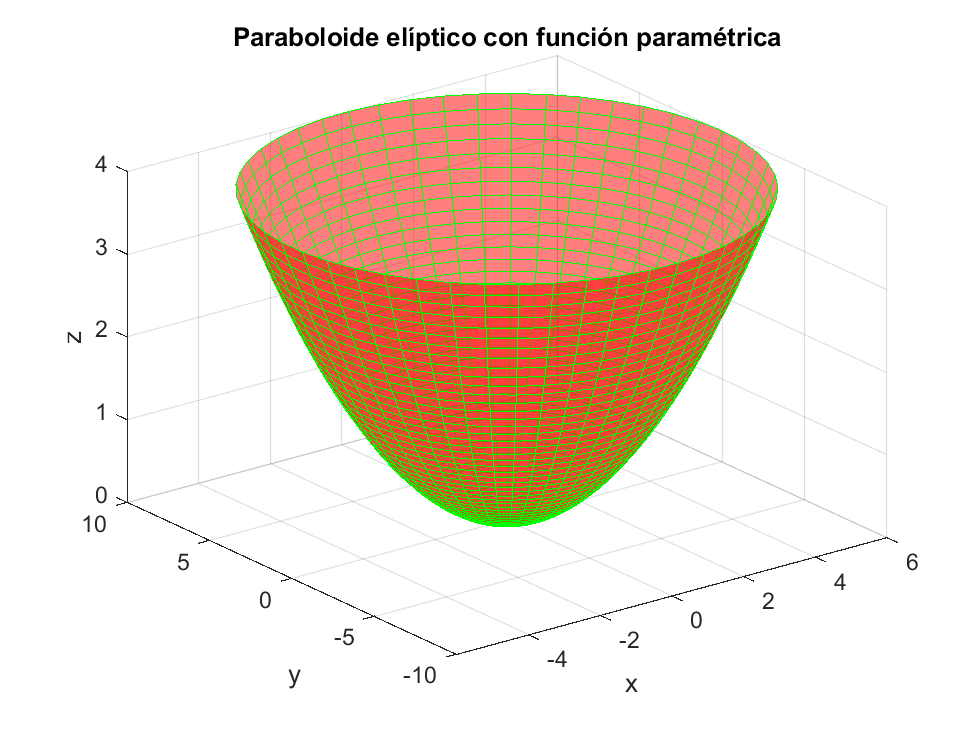

tl = linspace(0,2*pi,50);    % Valores de t (0 y 2pi)
ul = linspace(0,2,50);       % Valores de u (entre 0 y 2)

% Malla de valores t, u.
[t, u] = meshgrid(tl, ul);

% Calcula los valores de x, y, z para los puntos de la malla
x = 3*u.*cos(t);
y = 5*u.*sin(t);
z = u.^2;

% Gráfica de la función
surf(x, y, z,'FaceColor','r', 'FaceAlpha', 0.5, 'EdgeColor', 'g')
xlabel('x')
ylabel('y')
zlabel('z')
title('Paraboloide elíptico con función paramétrica')